## Correlation analysis

Juan E. Villegas, 07/10/2021, PRL NYUAD.

This script process the raw data from spectral measurememnts and computes the corss correlation between independent measurements of devices that are identical by design but have sensibly a different distribution of Au NPs on them. A high correaltion between a pair of responses would in general mean that both devices are impossible to be identified from each other. Given that changes that affect the FSR of the response might shift the overall spectral response without modifying any other information, we numerically shift one of the responses of a pairwise comparison to maximize their correlation and set a baseline that is harder to test when afterwards Hamming Distances get computed.

First extract the data from the H5 file. 

folder = '..\Datasets\';
file = 'AllDevices_Au1_Chips02_02_TM_user01_1705.h5';

filename = strcat(folder,file);
struct = h52struct(filename);
meas = struct.project.measurements; 

Let's check the data extracted from the 1st measurement set.

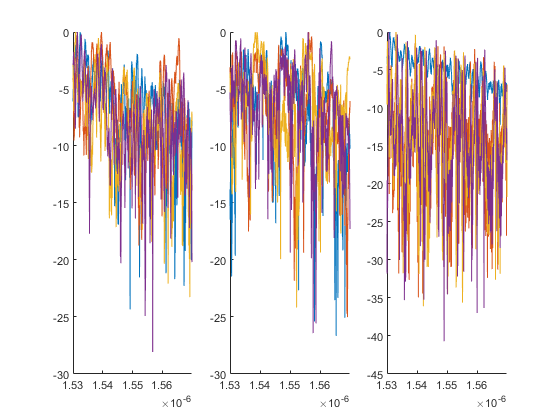

indexes{1} = [16, 14, 13, 12;   % Saved Device Numbers
          2, 3 , 4, 5 ]';    % Index in the measurements list  

indexes{2} = [20, 19, 18, 17;   % Saved Device Numbers
         6 , 7, 8,9 ]';    % Index in the measurements list 

indexes{3} = [24, 23, 22, 21;   % Saved Device Numbers
         11 , 13, 15, 16]';    % Index in the measurements list 

m = meas(1).spectra;
m(:,2) = m(:,2) - max(m(:,2));
lambda = m(:,1);

figure, clf, 
indp=1;

for index = indexes
    subplot(1,length(indexes),indp), hold on;
    index1 = sortrows(index{1}); 
    t_all_spectra = zeros(length(m),4);
    ind = 0;
    for i =index1(:,2)'
        ind= ind+1;
        m = meas(i).spectra;
        m(:,2) = m(:,2) - max(m(:,2)); % Normalization
        t_all_spectra(:,ind) = m(:,2);
        plot(m(:,1), m(:,2));
    end
    hold off;
    all_spectra{indp} = t_all_spectra;
    indp = indp+1;
end
hold off;

## **Statistical Analysis**

We  study the crosscorrelation of the signals, all refered to the first measurement, and create a new set of signals that are shifted in frequecy to maximaize the cross correlation with the reference one, this allows to take into account the possibility of having two difgferent devices that have simialr responses but shifted in frequency, such behviour could be derived from a very small variations of the FSR on resonant cavities that could be essentially tuned using temperature control over the chip. We limit the cross correlation test to a predifned spectral shift.  

First let's the the auto-correlation, several high peaks here would show a periodic behaviour 

shift = 9

shift = 88

shift = -167

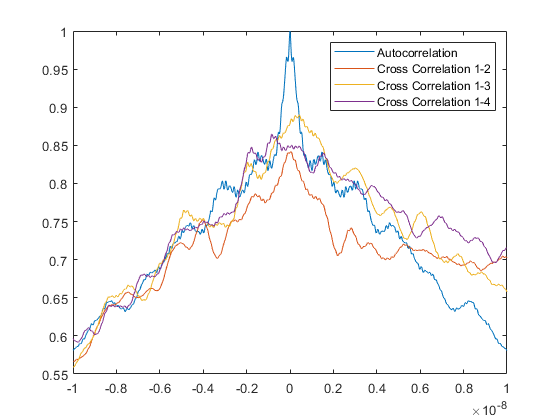

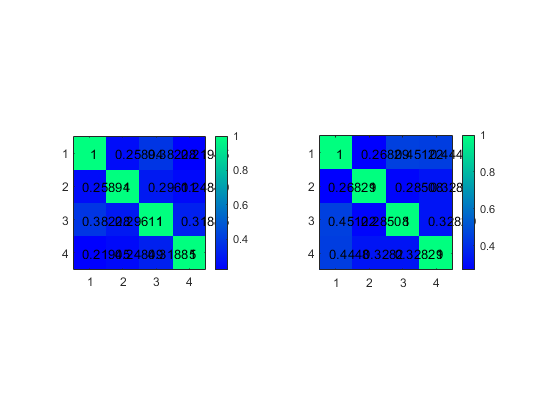

shift = 11

shift = -15

shift = 42

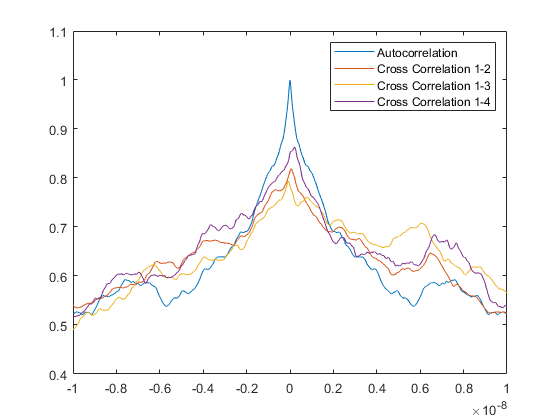

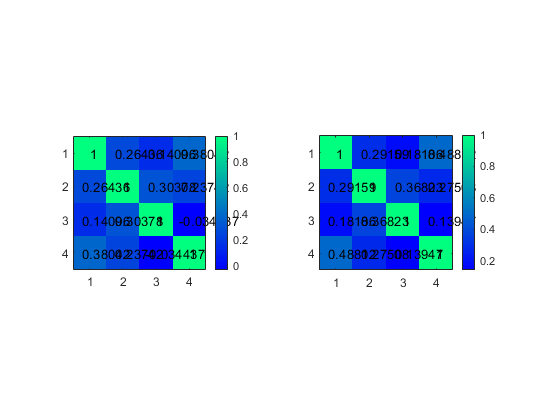

shift = 272

shift = 258

shift = 225

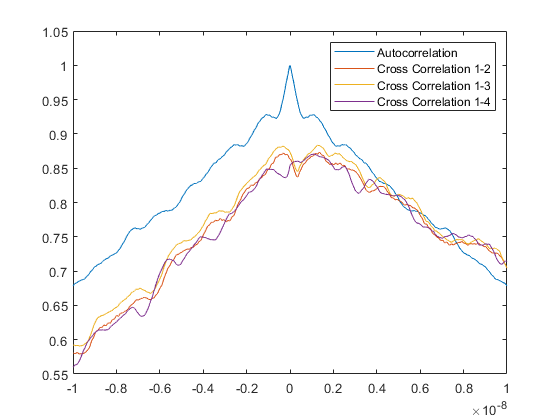

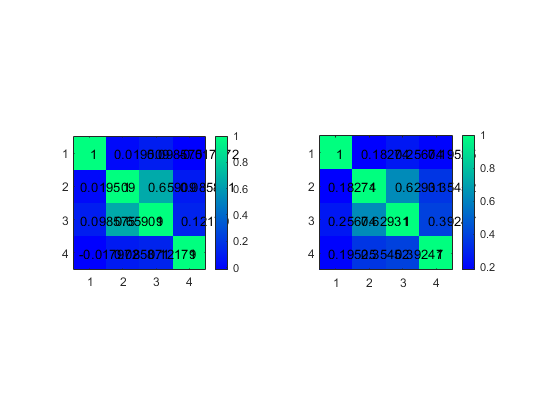

dl = lambda(2)-lambda(1);
xcorr_window = 10e-9; %in meters
xcorr_N = round(xcorr_window/dl);
figure;
for k = 1:length(all_spectra)
    dev_spectra= all_spectra{k};
    figure;
    [c,lags]=xcorr(dev_spectra(:,1),dev_spectra(:,1),xcorr_N,'normalized');
    plot(lags/xcorr_N*xcorr_window,c);  hold on;
    
    top_shift = 0; bot_shift = 0;
    datashift = zeros(size(dev_spectra));  endi = length(dev_spectra);
    datashift(:,1) = dev_spectra(:,1);
    for i = 2:4
        [c,lags]=xcorr(dev_spectra(:,1),dev_spectra(:,i),xcorr_N,'normalized');
        plot(lags/xcorr_N*xcorr_window,c); 
        
        [v,ind]= max(c);
        shift = lags(ind)
        if shift > 0
            datashift(1+shift:endi,i) = dev_spectra(1:endi-shift,i);
            top_shift = max(shift,top_shift);
        else
            datashift(1:endi+shift,i) = dev_spectra(1-shift:endi,i);
            bot_shift = min(shift,bot_shift);
        end
    end
    hold off;
    legend({'Autocorrelation','Cross Correlation 1-2','Cross Correlation 1-3',...
            'Cross Correlation 1-4'});
    
    % Crop the shifted data to avoid zero values and the general data to have the same length
    datashift = datashift(1+top_shift:endi,:);
    c_all = dev_spectra(1+top_shift:endi,:);
    c_lambda = lambda(1+top_shift:endi);
    
    endi = endi-top_shift;
    datashift = datashift(1:endi+bot_shift,:);
    c_all = c_all(1:endi+bot_shift,:);
    c_lambda = c_lambda(1:endi+bot_shift);

    A = [c_all(:,1) c_all(:,2) c_all(:,3) c_all(:,4)];
    R = corrcoef(A);
        
    A = [datashift(:,1) datashift(:,2) datashift(:,3) datashift(:,4)];
    R_shift = corrcoef(A);
    
    figure;
    subplot(1,2,1); plotcorr(R);
    subplot(1,2,2); plotcorr(R_shift);

    all_data{1} = c_all;
    all_data{2} = datashift;
end

We compute the correlation coefficients of the original samples and the shifted ones. These allows to actually test if the samples have become more 'similar' after the spectral shift. Note that although some crosscorrealtions of the shifted response are high, we should still be able to use them as PUFs as long as the following data processing takes into account higher order variations in the signal response.